# 中心極限定理の確認

## 1．一様分布の場合

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

pd2 = makedist("Exponential", mu=1.7);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:0.01:10;
plot(x, pdf(pd2, x))
hold on
    pd2_m = mean(pd2)

pd2_m = 1.7000

    pd2_s = std(pd2)

pd2_s = 1.7000

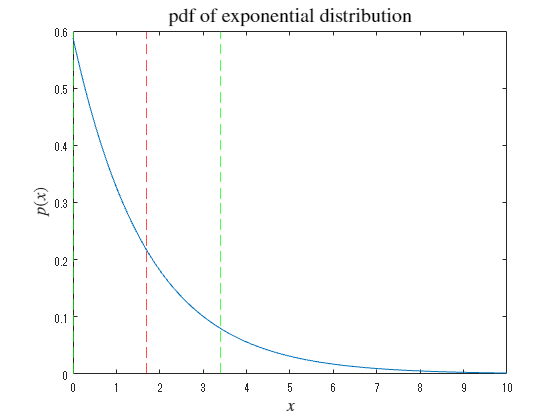

    xline(pd2_m, 'r--')
    xline(pd2_m + pd2_s, 'g--')
    xline(pd2_m - pd2_s, 'g--')
hold off
title('pdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

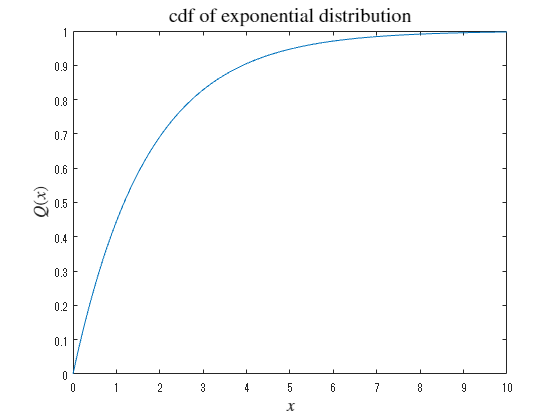


plot(x, cdf(pd2, x))
title('cdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd2 = random(pd2,[1000 1000])

rd2 =     2.5593    0.2297    0.6207    3.2100    3.0268    3.2093    0.4013    1.2231    0.2283    0.3917    0.9627    3.7966    2.3876    0.6310    1.8270    1.1282    0.8585    4.6123    4.9440    0.2772    3.3829    3.6161    0.2699    0.9999    2.6848    1.5700    0.8922    4.7233    1.9075    0.9324    1.3360    3.5826    0.2571    1.1346    1.6563    0.8037    0.3573    0.2499    3.9103    1.3527    5.1843    3.4572    0.8870    2.6453    3.0883    1.3020    2.2638    3.9159    1.5441    1.1738
    6.1607    0.7042    1.4374    0.1027    0.3004    0.5131    0.1502    1.5241    0.4029    0.4866    0.9983    0.0495    1.7750    0.6532    1.8208    0.2684    0.1280    1.4394    0.2816    1.3938    1.2134    1.7723    1.1773    2.6754    0.2414    0.7912    0.9102    1.1911    0.7792    0.0726    2.1575    0.2224    1.5597    0.4607    1.1633    0.1210    2.4665    2.4689    1.1638    0.3955    0.2745    2.5270    0.2375    0.6556    1.0528    3.3786    0.8770    5.4747    1.4383   

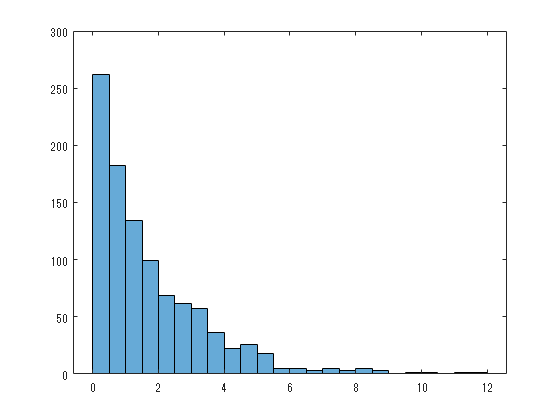

histogram(rd2(1,:))

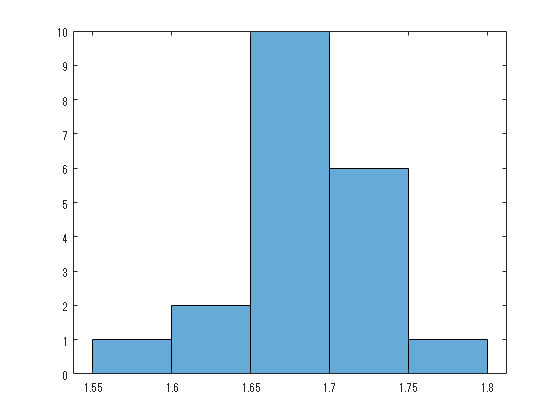

histogram(mean(rd2(1:20, :), 2))

## 2．指数分布の場合

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

pd2 = makedist("Exponential", mu=1.7);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:0.01:10;
plot(x, pdf(pd2, x))
hold on
    pd2_m = mean(pd2)
    pd2_s = std(pd2)
    xline(pd2_m, 'r--')
    xline(pd2_m + pd2_s, 'g--')
    xline(pd2_m - pd2_s, 'g--')
hold off
title('pdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)

plot(x, cdf(pd2, x))
title('cdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)


### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd2 = random(pd2,[1000 1000])
histogram(rd2(1,:))
histogram(mean(rd2(1:20, :), 2))
